## Circle Path Speed = 0.1 Simulation

%% Speed = 0.1 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadrotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 0.1;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [r*cos(t*speed); r*sin(t*speed); 4];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %0.1f%d\n", speed, r);

Running simulation for speed= 0.1 and radius = 2


[t,z,u,d,y] = sim.simulate(z0);

UAV Captured at time 7!!!
The runtime of every 1000th nlmpc call will display
(once per sim second, only if nlmpc is called)


fprintf("Simulation complete!\n");

Simulation complete!


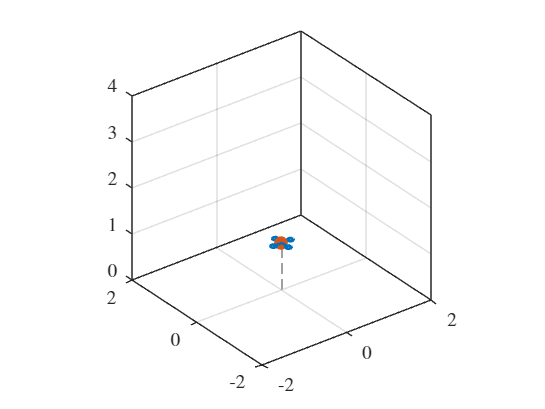

sim.animate(t, z, y);

## Circle Path Speed = 0.3 Simulation

%% Speed = 0.3 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadrotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 0.3;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [r*cos(t*speed); r*sin(t*speed); 4];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %0.3f %d\n", speed, r);

Running simulation for speed= 0.300 and radius = 2


[t,z,u,d,y] = sim.simulate(z0);

UAV Captured at time 7!!!
The runtime of every 1000th nlmpc call will display
(once per sim second, only if nlmpc is called)


fprintf("Simulation complete!\n");

Simulation complete!


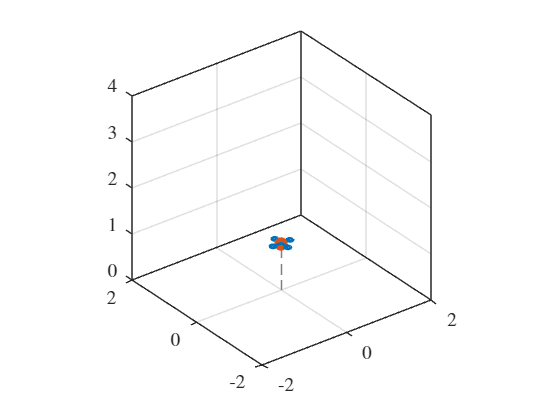

sim.animate(t, z, y);

## Circle Path Speed = 0.5 Simulation

%% Speed = 0.5 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadrotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 0.5;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [r*cos(t*speed); r*sin(t*speed); 4];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %0.5f %d\n", speed, r);

Running simulation for speed= 0.50000 and radius = 2


[t,z,u,d,y] = sim.simulate(z0);

UAV Captured at time 9!!!
The runtime of every 1000th nlmpc call will display
(once per sim second, only if nlmpc is called)


fprintf("Simulation complete!\n");

Simulation complete!


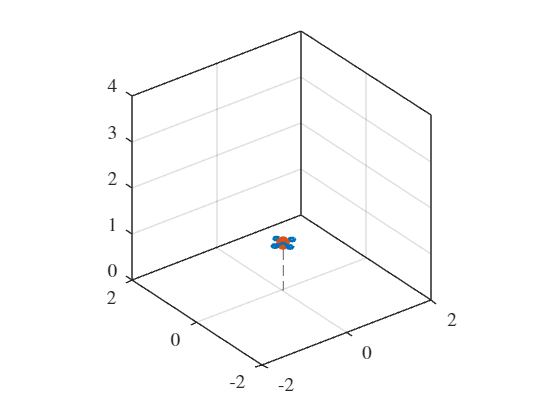

sim.animate(t, z, y);

## Circle Path Speed = 0.7 Simulation

%% Speed = 0.7 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadraotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 0.7;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [r*cos(t*speed); r*sin(t*speed); 4];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %0.7f%d\n", speed, r);

Running simulation for speed= 0.7000000 and radius = 2


[t,z,u,d,y] = sim.simulate(z0);
fprintf("Simulation complete!\n");

Simulation complete!


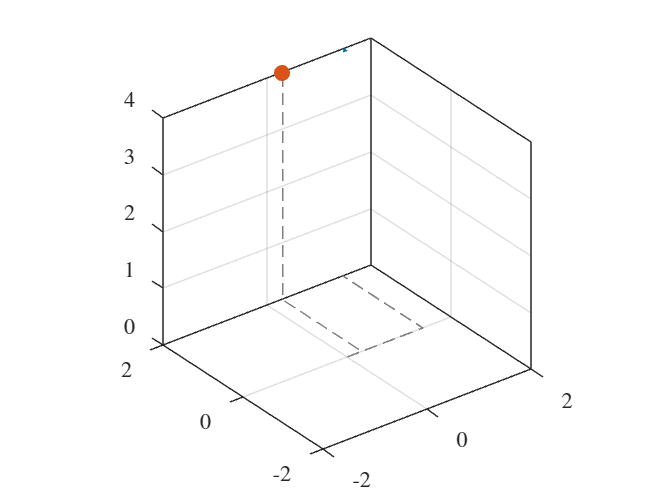

sim.animate(t, z, y);

## Line Path Speed 1 Simulation

%% Speed = 1 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadrotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 1;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [4 * cos(pi * speed * t)^2 - 2; 0; 3];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %1f%d\n", speed, r);

Running simulation for speed= 1.000000 and radius = 2


[t,z,u,d,y] = sim.simulate(z0);

UAV Captured at time 2!!!
The runtime of every 1000th nlmpc call will display
(once per sim second, only if nlmpc is called)


fprintf("Simulation complete!\n");

Simulation complete!


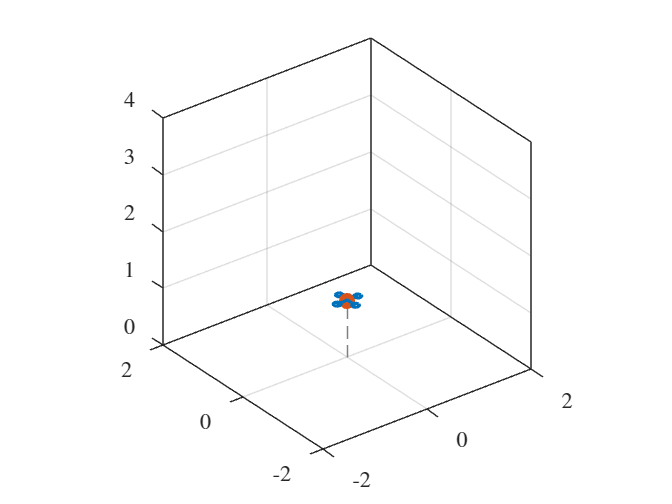

sim.animate(t, z, y);

## Line Path Speed 2 Simulation

%% Speed = 2 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadrotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 2;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [4 * cos(pi * speed * t)^2 - 2; 0; 3];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %2f%d\n", speed, r);

Running simulation for speed= 2.0000002


[t,z,u,d,y] = sim.simulate(z0);

UAV Captured at time 2!!!
The runtime of every 1000th nlmpc call will display
(once per sim second, only if nlmpc is called)


fprintf("Simulation complete!\n");

Simulation complete!


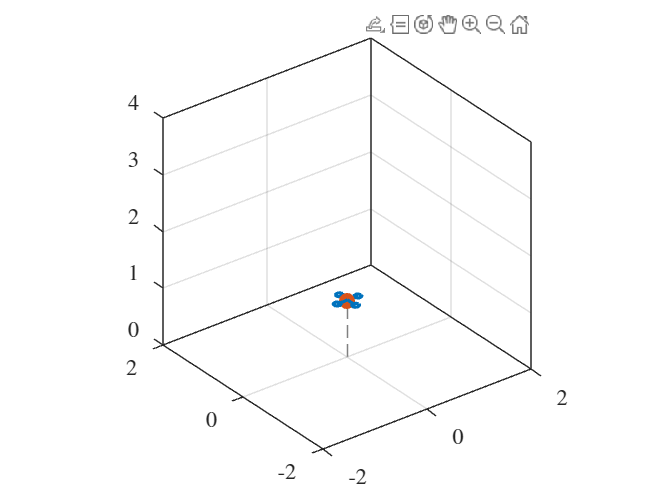

sim.animate(t, z, y);

## Line Path Speed 3 Simulation

%% Speed = 3 Simulation
[quad, ctrl, dt] = lqr_vel_sim_test_();  % Setup quadrotor and controller

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.
Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


speed = 3;  % Define the intruder's speed
r = 2;  % Radius of the path
path = @(t) [4 * cos(pi * speed * t)^2 - 2; 0; 3];  % Path function for the intruder

% Define disturbances
dist = struct("r", @(t,z) 0*[sin(t); sin(2*t); sin(4*t)],...
    "n", @(t,z) 0*[0.1; 0.01; 0.1]);

% Create intruder and run simulation
intruder = uav(path, dist);
sim = simulator(quad, ctrl, intruder);
sim.simtime = [0 20];
sim.timestep = dt;
sim.epsilon = 0.1;
z0 = zeros(12,1);

fprintf('--------------------------\n');

--------------------------


fprintf("Running simulation for speed= %3f%d\n", speed, r);

Running simulation for speed= 3.0000002


[t,z,u,d,y] = sim.simulate(z0);

UAV Captured at time 2!!!
The runtime of every 1000th nlmpc call will display
(once per sim second, only if nlmpc is called)


fprintf("Simulation complete!\n");

Simulation complete!


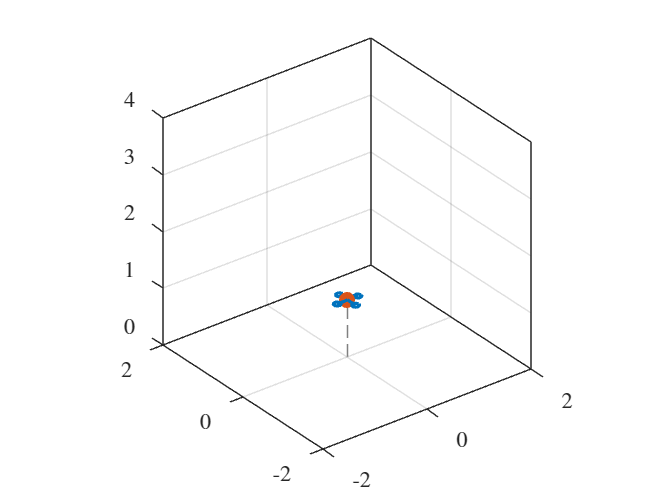

sim.animate(t, z, y);

# Simulation Setup

function [quad, ctrl, dt] = lqr_vel_sim_test_()
    % Clear existing figures and variables
    clc;
    close all;

    % Define the necessary paths
    addpath('../quadrotor_sim/src');
    addpath('../pred');

    % Define quadrotor parameters
    g = 9.81;  % The gravitational acceleration [m/s^2]
    l = 0.2;   % Distance from the center of mass to each rotor [m]
    m = 0.5;   % Total mass of the quadrotor [kg]
    I = [1.24, 1.24, 2.48];  % Mass moment of inertia [kg m^2]
    mu = 3.0;  % Maximum thrust of each rotor [N]
    sigma = 0.01;  % The proportionality constant relating thrust to torque [m]

    % Create quadrotor object
    quad = quadrotor(g, l, m, diag(I), mu, sigma);
    dt = 0.01;

    % Create controller
    useMpc = true;
    ctrl = lqr_velocity_controller(quad, dt, useMpc);
end